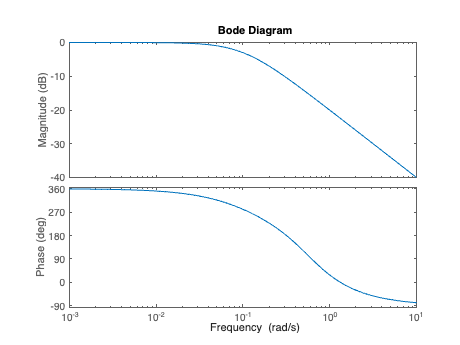

%P1
figure
G=tf(0.1,[1 0.1],'InputDelay',6);
G_pade=pade(G,2);
bode(G_pade);

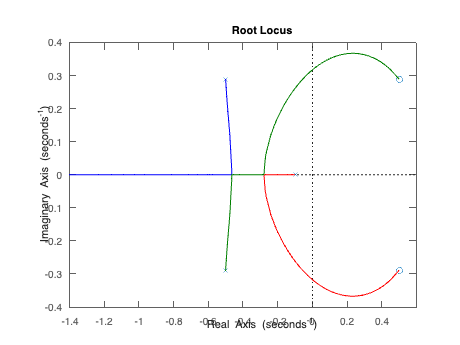


%P2
figure
rlocus(G_pade);

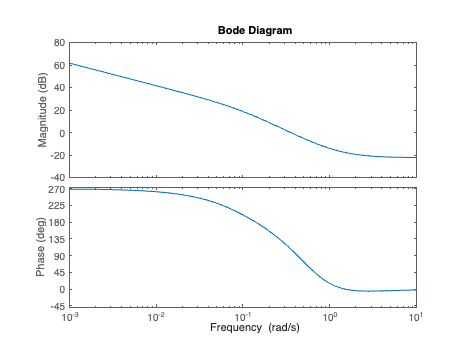


%P4
%a
figure
D=0.76*tf([1 2.52 1.587],[1,0]);
GD_pade=pade(G*D,2);
bode(GD_pade);

%b
[gm,pm,wg,wp]=margin(GD_pade)

gm = 0.1979

pm = -71.9194

wg = 0.1403

wp = 0.3539


%P6
%a
Gz=tf(0.1,[1 0.1 0],'InputDelay',6);
c2d(Gz,2)

ans =
 
             0.1873 z + 0.1752
  z^(-3) * ----------------------
           z^2 - 1.819 z + 0.8187
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties
